# Filas MMm

A figura abaixo representa um sistema de filas MMm.

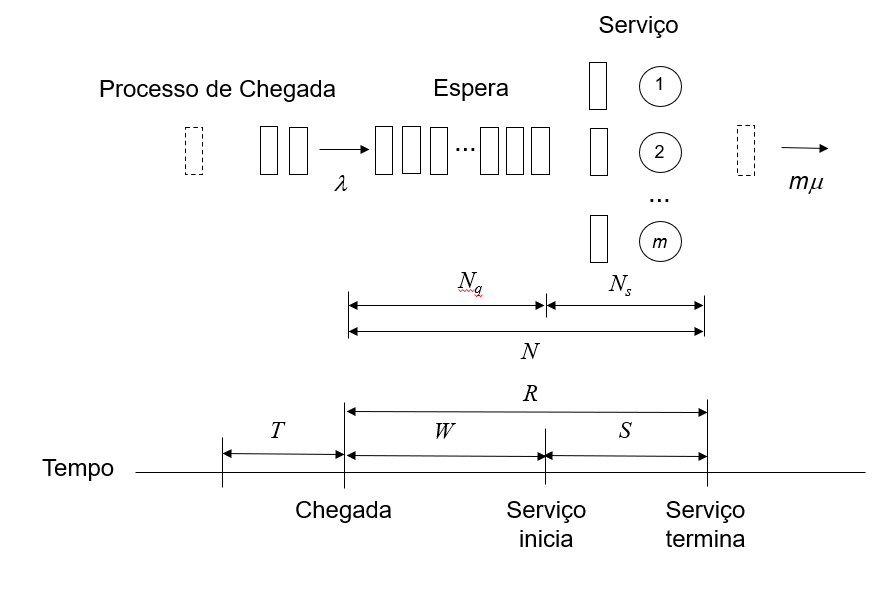

O sistema possui $m$ servidores e uma fila de espera de tamanho infinito.

As tarefas chegam segundo um processos de Poisson com taxa $\lambda$, ou seja, o tempo decorrido entre duas chegadas consecutivas (variável $T$) tem distribuição exponencial com média $\frac{1}{\lambda }$.

A taxa de serviço em cada servidor é $\mu$, ou seja, o tempo de serviço para cada tarefa (variável $S$) tem distribuição exponencial com media $\frac{1}{\mu }$.

A variável $R$ representa o tempo de resposta do sistema, ou seja, o tempo decorrido desde a chegada no sistema até a saída do mesmo.

A variável $W$ representa o tempo de espera na fila, ou seja, o tempo que uma tafefa permanece esperando na fila.

A variável $N$representa a quantidade de tarefas dentro do sistema.

A variável $N_q$ representa a quantidade de tarefas na fila.

A variável $N_s$ representa a quantidade de tarefas sendo servidas.

Os parâmetros do sistema são:

- Quantidade de servidores: m

- Taxa de chegada: lambda

- Taxa de serviço: mu

- Quantidade de eventos simulados: nsim

A taxa de serviço precisa ser maior do que a taxa de chegada (mu > lambda)

m =2

m = 2

lambda =2.2

lambda = 2.2000

mu = 10

mu = 10

nsim =20000

nsim = 20000

if (lambda >= m*mu)
    disp('A taxa de serviço tem que ser maior do que a taxa de chegada');
end

## Define e inicia variáveis globais

O sistema precisa de um conjunto de variáveis usadas por todas as funções (variáveis globais), que saõ definidas e iniciadas a seguir.

% Variaveis globais
global tamanho_da_fila
global limite_da_fila
global perda
global tamanho_fila_x_tempo
global tempo_do_ultimo_evento
global tempo_total_de_espera
global tempo
global Agenda
global nServidores
global estado_servidor
global tempo_de_servico_medio
global total_de_tempo_de_servico
global tempo_medio_entre_chegadas
global numero_de_eventos
global servidor
global estado_do_sistema
global estado_sistema_x_tempo

nServidores = m;
Agenda = zeros(1, m+1);

limite_da_fila = 10000;                   % tamanho limite da fila
perda = 0;
tempo_medio_entre_chegadas = 1/lambda;	  % tempo médio entre chegadas  
tempo_de_servico_medio=1/mu;              % tempo médio de serviço          

estado_servidor = zeros(1, nServidores);  % estado do servidor (livre)
tamanho_da_fila = 0;                      % tamanho da fila
tempo_do_ultimo_evento = 0.0;             % data de ocorrência do último evento 
tempo_total_de_espera = 0.0;              % tempo total de espera na fila
total_de_tempo_de_servico = 0.0;          % total de tempo de servico
tamanho_fila_x_tempo = 0.0;               % tamanho da fila multiplicado pela duracao do ultimo evento

estado_do_sistema = 0;
estado_sistema_x_tempo = 0.0;             % contador area_serve_status

% Agenda a primeira chegada
% O vetor agenda tem nServidores+1 entradas, uma para cada servidor e a
% última para agendar a próxima chegada
tempo = exprnd(tempo_medio_entre_chegadas, 1, 1);
Agenda(1, nServidores+1) = tempo;

% Inicializa quantidade de eventos que passam pelo sistema
numero_de_eventos = 1; 


## Simulação

O código a seguir executa a simulação.

while(numero_de_eventos < nsim)
    % Encontra indice do proximo evento (menor tempo armazenado na Agenda)
    proximo_evento = find(Agenda == min(Agenda),1);

    % Determina tipo do próximo evento (chegada ou saída)
    if (proximo_evento > m)
        tipo_proximo_evento = 1; % chegada
    else
      tipo_proximo_evento = 0; % saída
      servidor = proximo_evento;
    end
    
    % Recupera o tempo do próximo evento
    tempo = Agenda(proximo_evento);

    % Atualiza os acumuladores estatisticos
    atualiza; 			 	

    % Processa o próximo evento de acordo com o tipo
    if (tipo_proximo_evento == 1)
        chegada;          % Chama rotina de chegada
    else
        saida;			  % Chama rotina de saida
    end

end

## Resultados da simulação

mostra_estatisticas(lambda, mu, m, nsim);

--------------------------------------------------------------
Numero de eventos                                 : 20000
Lambda                                            : 2.2000
Mu                                                : 10.0000
Nservidores                                       : 2.0000
Ro                                                : 0.1100
epsilon                                           : 0.0218
P0                                                : 0.8018
Taxa de perda                                     : 0.0000
--------------------------------------------------------------
Tempo medio na fila (simulado)                    : 0.0013
Numero medio de elementos na fila (simulado)      : 0.0029
Tempo medio de servico (simulado)                 : 0.0997
Numero medio de elementos servidos (simulado)     : 0.2193
Tempo medio de resposta (simulado)                : 0.1010
Numero medio de elemento no sistema (simulado)    : 0.2222
Taxa de utilizacao do sistema (simulado)        